% define a upsample filter
Rup = 16;
hFilDesign = fdesign.pulseshaping(Rup, 'Raised Cosine', 'Nsym,Beta', Rup,0.50);
hFil = design(hFilDesign);

% generate random data in range 4
d = randi([0 3], 100, 1); 

% generate tx signal
sym = pskmod(d, 4, pi/4);
xmt = filter(hFil, upsample(sym, Rup));

% create the plot
hScope = comm.ConstellationDiagram;

% set params
hScope.SamplesPerSymbol = Rup;
hSocpe.ShowTrajectory = true;

% fit scale
hFil.Numerator = hFil.Numerator / max(hFil.Numerator);
xmt = filter(hFil, upsample(sym, Rup));

% show data
update(hScope, xmt);

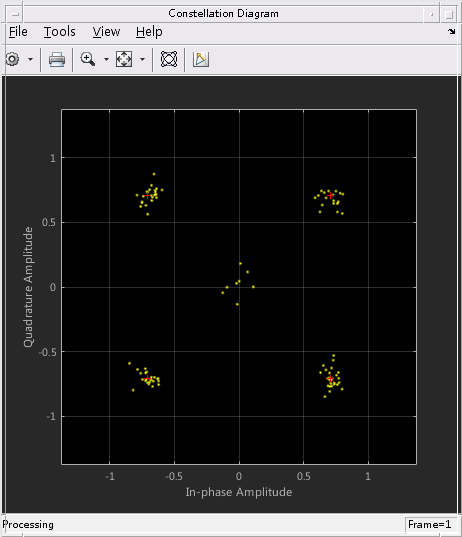

% generate rx signal via channel
rcv = awgn(xmt, 20, 'measured');

% update data
reset(hScope);
update(hScope, rcv);


% turn off traj
hSocpe.ShowTrajectory = false;
